**Cambio de Escala**

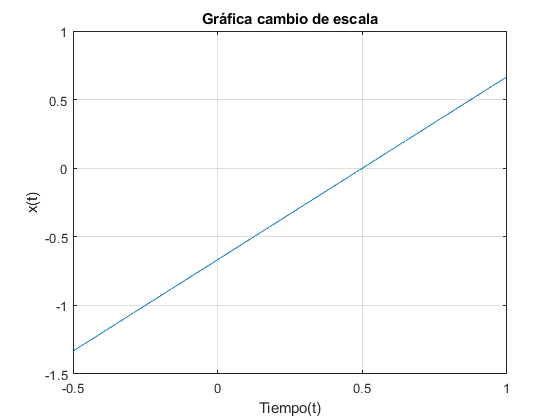

%-----Cambio de escala
Fs=100;
A=2;
t=-1/A:1/Fs:2/A;
L=3000;         %Longitud de la señal 
s=((4/3)*t-2/3);%Cambio de escala
Y=fft(s,L);     %Aplicando transformada rápida

plot(t,s);
title('Gráfica cambio de escala')
xlabel('Tiempo(t)');
ylabel('x(t)');
grid on

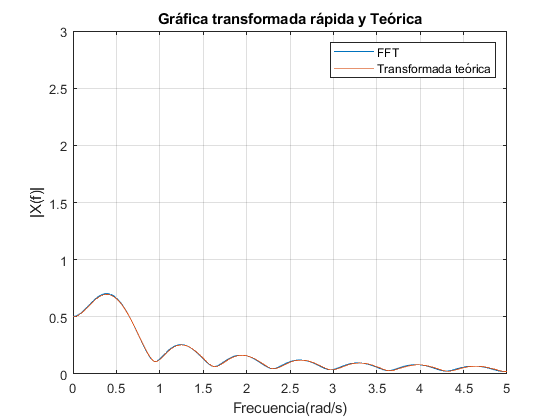

figure   

P=abs(Y/Fs);
f=linspace(0,Fs,numel(P));

plot(f,P)
axis ([0 5 0 3])
title('Gráfica transformada rápida y Teórica')
xlabel('Frecuencia(rad/s)')
ylabel('|X(f)|')
grid on

syms t f;       %Variables simbólicas
e=2;
xce=((4/3)*t-2/3);%Cambio de escala  %
yce=int(xce*exp(-1i*2*pi*f*t),t,-1/e,2/e); %Transformada de Fourier teórica
hold on         %sobreposición
fplot(f,abs(yce),[0 5])
legend('FFT','Transformada teórica')
grid on

figure
